# Estabilidad y Convergencia

iterados = zeros(1,20);
e = exp(1);
iterados(1) = 0.36787;

for i = 2:20
    iterados(i) = 1 - i*iterados(i-1);
end

disp("Iteracion 20: "+iterados(20));

Iteracion 20: 22969444961625.53


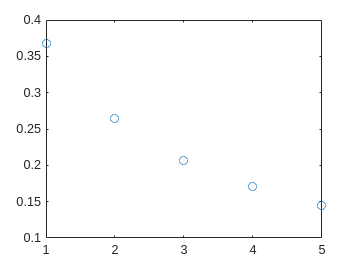

plot(iterados(1:5), "o");

I20 = 0.04762;
In = zeros(1,20);
In(20) = I20;
for n = 20:-1:2
    In(n-1) = (1-In(n)) / n;
end
disp("I9: "+In(9))

I9: 0.091612


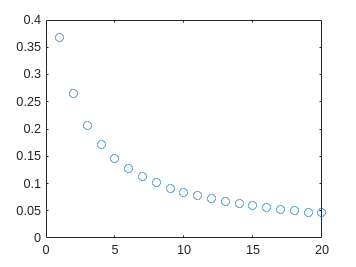

I9_real = 0.0916;
error_absoluto = abs(I9_real - In);
error_relativo = (error_absoluto / I9_real) * 100;
plot(In, "o");